% Set the number of required maps to 100,000, this is also the name of the
% map variable
RequiredMaps = 100000;

% Load the data from the specified .mat file, dynamically naming the file based on RequiredMaps
% The loaded data will contain a variable named 'AllSolvedData'
load("2D\DL\AllSolvedData" + RequiredMaps + ".mat", 'AllSolvedData');

% Assign the loaded data to a new variable named 'Database' for convenience
Database = AllSolvedData;

% Create a state space object for SE(2) space, which represents planar motion (x, y, and orientation)
statespace = stateSpaceSE2;

% Set the bounds for the state space:
% - x-coordinate: [0, 20]
% - y-coordinate: [0, 20]
% - orientation: [-π, π]
statespace.StateBounds = [[0 20]; [0 20]; [-3.1416 3.1416]];


% Create a motion planning neural network (MPNet) object for SE(2) space
mpnet = mpnetSE2;

% Set the loss weights for the neural network training
% - The first two weights (100 each) might correspond to positional error terms in x and y coordinates
% - The third weight (0) likely corresponds to the error term in orientation, which might be less important or not used
mpnet.LossWeights = [100 100 0];

% Set the encoding size for the neural network
mpnet.EncodingSize = [9 9];


% Define the split ratio for training and validation data
% 80% of the data will be used for training, and 20% will be used for validation
split = 0.8;

% Split the database into training and validation datasets
% - The training data consists of the first 80% of the Database
% - The validation data consists of the remaining 20% of the Database
trainData = Database(1:int32(split*end), :);

% The validation data starts right after the training data and goes to the end of the Database
validationData = Database(int32(split*end)+1:end, :);



% Prepare the training data for the motion planning neural network (MPNet)
% - The function 'mpnetPrepareData' preprocesses the training data 'trainData' for use with 'mpnet'
% - The result is stored in 'dsTrain', which will be used for training the neural network
dsTrain = mpnetPrepareData(trainData, mpnet);

% Prepare the validation data for the motion planning neural network (MPNet)
% - The function 'mpnetPrepareData' preprocesses the validation data 'validationData' for use with 'mpnet'
% - The result is stored in 'dsValidation', which will be used for validating the neural network
dsValidation = mpnetPrepareData(validationData, mpnet);


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:12        0.001                            98.991
            1        1       00:00:12        0.001          98.074                  
           50        1       00:00:26        0.001          1.2084                  
          100        1       00:00:29        0.001         0.55277                  
          150        1       00:00:32        0.001         0.36522                  
          200        1       00:00:35        0.001          0.2962                  
          250        1       00:00:38        0.001         0.25454                  
          300        1       00:00:41        0.001         0.21924                  
          350        1       00:00:44        0.001         0.19385                  
          400        1       00:00:47        0.001         0.1753

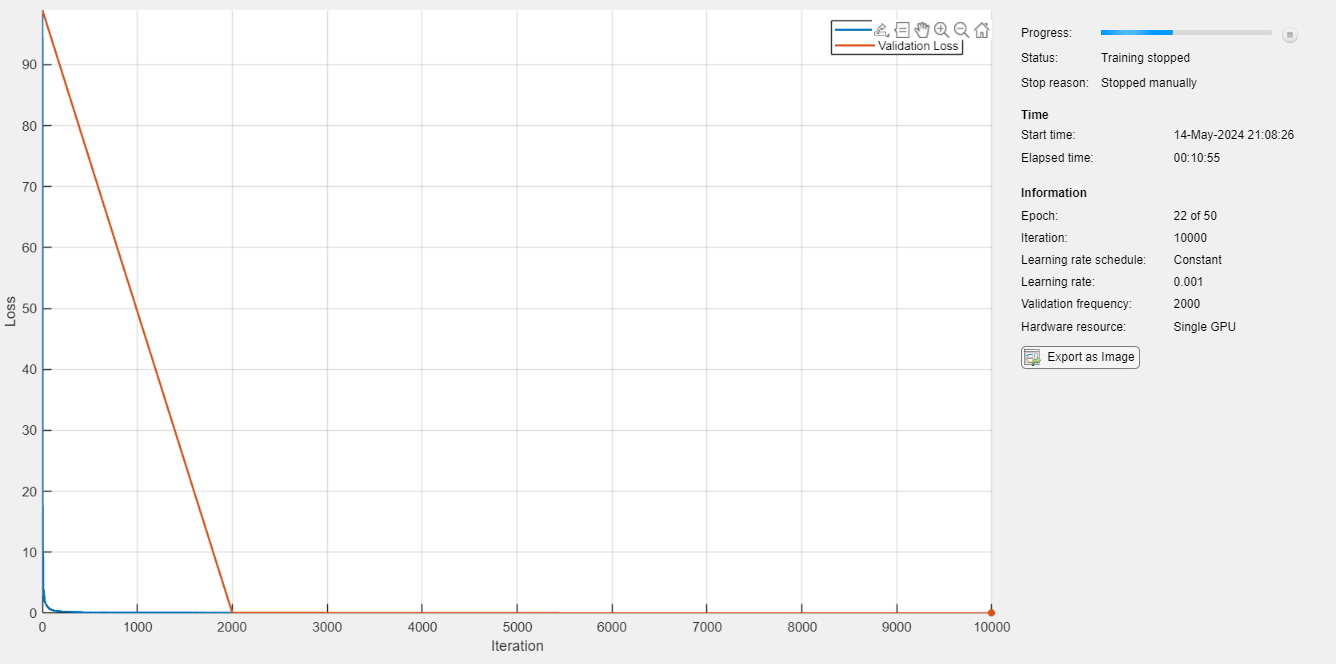

%Define the training options for the neural network using the "adam" optimizer
%Set the mini-batch size to 2048, which is the number of samples per gradient update
% Set the maximum number of epochs to 50, which is the number of complete passes through the training dataset
% Shuffle the data every epoch to improve training stability and generalization
% Provide the validation dataset for evaluating the model during training
% Set the frequency of validation to every 2000 iterations
% Display the training progress plot

options = trainingOptions("adam",...
        MiniBatchSize=2048,...
        MaxEpochs=50,...
        Shuffle="every-epoch",...
        ValidationData=dsValidation,...
        ValidationFrequency=2000,...
        Plots="training-progress");
% Train the neural network using the prepared training dataset
% - 'dsTrain' is the training data
% - 'mpnet.Network' is the initial network to be trained
% - '@mpnet.loss' is the custom loss function for training
% - 'options' specifies the training options
% - 'net' is the trained network
% - 'info' contains information about the training process
[net, info] = trainnet(dsTrain, mpnet.Network, @mpnet.loss, options);

% Update the 'mpnet' object with the trained network
mpnet.Network = net;



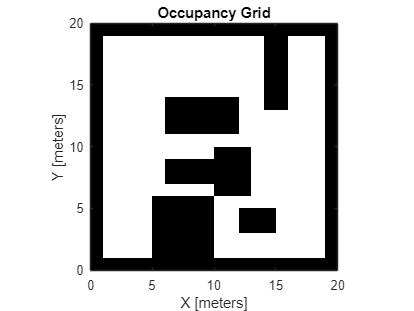

stateSamplerDL =   stateSamplerMPNET with properties:

               StateSpace: [1×1 stateSpaceSE2]
    MotionPlanningNetwork: [1×1 mpnetSE2]
              Environment: [1×1 occupancyMap]
               StartState: [18 9 0]
                GoalState: [9 16 0]
        MaxLearnedSamples: 50
            GoalThreshold: 1


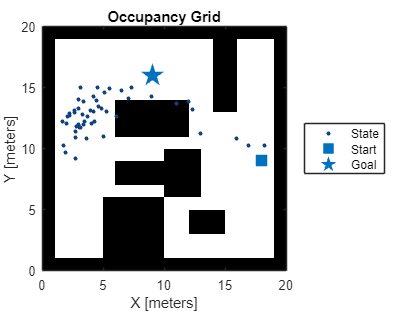

%Save it
save("2D\DL\mpnet.mat", "mpnet")